# Comparing our results with Stefanini

Comparing our results to Stefanini, using one session from us, and one from him. With an alpha function using tau = 0.1 and 0.5 s. Using the time-breaking and time-preserving shuffle.

## High tau (0.5s) and time-preserving

### Stefanini:

tau = 0.5;
fs_sess = OpenField('../fabio_data/dhpc09_behavior.txt', '../fabio_data/dhpc09_cnmfe.mat', tau);

t_ = tic;
[~, ~, ~, fs_err, fs_std] = fs_sess.decode(false, true);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


toc(t_)

Elapsed time is 117.072787 seconds.


fprintf('Real data: %f +- %f\n', fs_err, fs_std);

Real data: 11.560230 +- 2.119607


t_ = tic;
[~, ~, ~, fs_err_shuf, fs_std_shuf] = fs_sess.decode(true, true);
toc(t_)

Elapsed time is 68.607520 seconds.


fprintf('Shuffled data: %f +- %f\n', fs_err_shuf, fs_std_shuf);

Shuffled data: 6.028087 +- 1.184489


res.high_tau_pres_fs = fs_err;
res.high_tau_pres_fs_std = fs_std;
res.high_tau_pres_fs_shuf = fs_err_shuf;
res.high_tau_pres_fs_shuf_std = fs_std_shuf;

## Low tau (0.1s) and time-preserving

### Stefanini:

tau = 0.1;
fs_sess = OpenField('../fabio_data/dhpc09_behavior.txt', '../fabio_data/dhpc09_cnmfe.mat', tau);

t_ = tic;
[~, ~, ~, fs_err, fs_std] = fs_sess.decode(false, true);
toc(t_)

Elapsed time is 74.301593 seconds.


fprintf('Real data: %f +- %f\n', fs_err, fs_std);

Real data: 16.058129 +- 2.108389


t_ = tic;
[~, ~, ~, fs_err_shuf, fs_std_shuf] = fs_sess.decode(true, true);
toc(t_)

Elapsed time is 64.115330 seconds.


fprintf('Shuffled data: %f +- %f\n', fs_err_shuf, fs_std_shuf);

Shuffled data: 12.912975 +- 1.779970


res.low_tau_pres_fs = fs_err;
res.low_tau_pres_fs_std = fs_std;
res.low_tau_pres_fs_shuf = fs_err_shuf;
res.low_tau_pres_fs_shuf_std = fs_std_shuf;

## High tau (0.5s) and time-breaking

### Stefanini:

tau = 0.5;
fs_sess = OpenField('../fabio_data/dhpc09_behavior.txt', '../fabio_data/dhpc09_cnmfe.mat', tau);

t_ = tic;
ss_res = fs_sess.decode_spikeshuf(false);
toc(t_);

Elapsed time is 61.499210 seconds.


fprintf('Spikeshuf, %f +- %f\n', mean(ss_res.fs_metric_spikeshuf), std(ss_res.fs_metric_spikeshuf));

Spikeshuf, 12.378387 +- 1.837759


t_ = tic;
ss_res_auto = fs_sess.decode_spikeshuf(true);
toc(t_);

Elapsed time is 75.989162 seconds.


fprintf('Spikeshuf auto, %f +- %f\n', mean(ss_res_auto.fs_metric_spikeshuf), std(ss_res_auto.fs_metric_spikeshuf));

Spikeshuf auto, 11.616128 +- 3.428000


res.high_tau_break_fs = median(ss_res_auto.fs_metric_spikeshuf);
res.high_tau_break_fs_std = std(ss_res_auto.fs_metric_spikeshuf);
res.high_tau_break_fs_shuf = median(ss_res.fs_metric_spikeshuf);
res.high_tau_break_fs_shuf_std = std(ss_res.fs_metric_spikeshuf);

## Low tau (0.1s) and time-breaking

### Stefanini:

tau = 0.1;
fs_sess = OpenField('../fabio_data/dhpc09_behavior.txt', '../fabio_data/dhpc09_cnmfe.mat', tau);

t_ = tic;
ss_res = fs_sess.decode_spikeshuf(false);
toc(t_);

Elapsed time is 65.852307 seconds.


fprintf('Spikeshuf, %f +- %f\n', mean(ss_res.fs_metric_spikeshuf), std(ss_res.fs_metric_spikeshuf));

Spikeshuf, 15.602608 +- 2.667994


t_ = tic;
ss_res_auto = fs_sess.decode_spikeshuf(true);
toc(t_);

Elapsed time is 71.462308 seconds.


fprintf('Spikeshuf auto, %f +- %f\n', mean(ss_res_auto.fs_metric_spikeshuf), std(ss_res_auto.fs_metric_spikeshuf));

Spikeshuf auto, 16.319630 +- 2.093548


res.low_tau_break_fs = median(ss_res_auto.fs_metric_spikeshuf);
res.low_tau_break_fs_std = std(ss_res_auto.fs_metric_spikeshuf);
res.low_tau_break_fs_shuf = median(ss_res.fs_metric_spikeshuf);
res.low_tau_break_fs_shuf_std = std(ss_res.fs_metric_spikeshuf);

## Our results, preserving shuffle, 0.5s tau

sm = SessManager;
d = sm.cons_usable(69);

load(d.source_path)

S = tracesEvents.HD_spikes;

C = tau_conv(S, 0.5, 20);

opt = DecodeTensor.default_opt;
[~, ~, tr_s, tr_e, tr_dir, tr_bins, ~] = DecodeTensor.new_sel(tracesEvents.position(:,1), opt);
data_tensor = DecodeTensor.construct_tensor(C, tr_bins, opt.n_bins, tr_s, tr_e);
d.data_tensor = data_tensor;
d.tr_dir = tr_dir;
d.opt = opt;

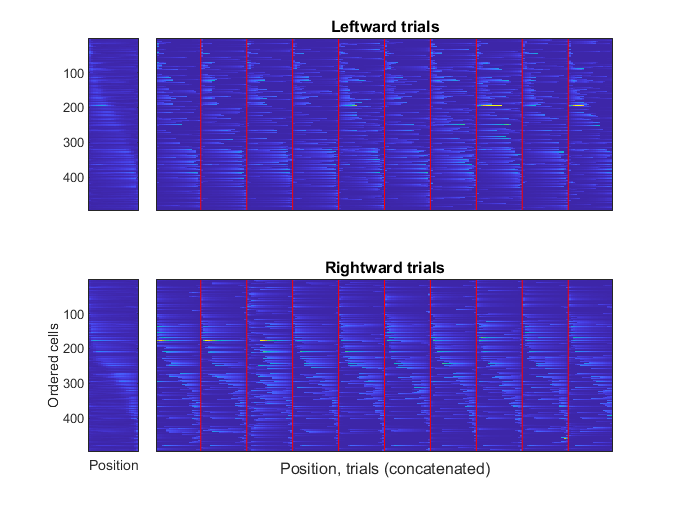

figure;
d.vis;

t_ = tic;
mean_err = d.basic_decode(false, [], []);
toc(t_);

Elapsed time is 65.697846 seconds.


fprintf('Mean err, real: %f\n', mean_err);

Mean err, real: 3.080019


t_ = tic;
mean_err_shuf = d.basic_decode(true, [], []);
toc(t_);

Elapsed time is 57.845174 seconds.


fprintf('Mean err, shuf: %f\n', mean_err_shuf);

Mean err, shuf: 1.805030


res.high_tau_pres_us = mean_err;
res.high_tau_pres_us_shuf = mean_err_shuf;

## Our results, preserving shuffle, 0.1s tau

C = tau_conv(S, 0.1, 20);

opt = DecodeTensor.default_opt;
[~, ~, tr_s, tr_e, tr_dir, tr_bins, tr_dir_bins] = DecodeTensor.new_sel(tracesEvents.position(:,1), opt);
data_tensor = DecodeTensor.construct_tensor(C, tr_bins, opt.n_bins, tr_s, tr_e);
d.data_tensor = data_tensor;
d.tr_dir = tr_dir;
d.opt = opt;

within_trial = false(size(tr_dir_bins));
for i = 1:numel(tr_s)
    within_trial(tr_s(i):tr_e(i)) = true;
end

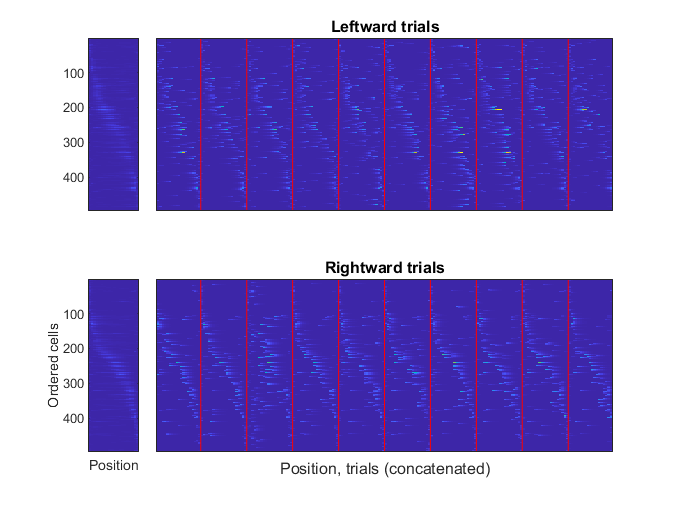

figure;
d.vis;

t_ = tic;
mean_err = d.basic_decode(false, [], []);
toc(t_);

Elapsed time is 97.291659 seconds.


fprintf('Mean err, real: %f\n', mean_err);

Mean err, real: 3.721970


t_ = tic;
mean_err_shuf = d.basic_decode(true, [], []);
toc(t_);

Elapsed time is 62.274630 seconds.


fprintf('Mean err, shuf: %f\n', mean_err_shuf);

Mean err, shuf: 2.063086


res.low_tau_pres_us = mean_err;
res.low_tau_pres_us_shuf = mean_err_shuf;

## Trying the breaking shuffle, with tau = 0.1s

tr_dir_bins_intrial = tr_dir_bins .* (-1).^within_trial;
S_shuf = fshuffle(S, tr_dir_bins_intrial, false);
C_shuf = tau_conv(S_shuf, 0.1, 20);
data_tensor = DecodeTensor.construct_tensor(C_shuf, tr_bins, opt.n_bins, tr_s, tr_e);
d.data_tensor = data_tensor;
d.tr_dir = tr_dir;
d.opt = opt;

t_ = tic;
mean_err_breaking = d.basic_decode(false, [], []);
toc(t_);

Elapsed time is 60.253904 seconds.


fprintf('Mean err, breaking shuf: %f\n', mean_err_breaking);

Mean err, breaking shuf: 2.845986


Auto control

tr_dir_bins_intrial = tr_dir_bins .* (-1).^within_trial;
S_shuf = fshuffle(S, tr_dir_bins_intrial, true);
C_shuf = tau_conv(S_shuf, 0.1, 20);
data_tensor = DecodeTensor.construct_tensor(C_shuf, tr_bins, opt.n_bins, tr_s, tr_e);
d.data_tensor = data_tensor;
d.tr_dir = tr_dir;
d.opt = opt;

t_ = tic;
mean_err_breaking_auto = d.basic_decode(false, [], []);
toc(t_);

Elapsed time is 61.104373 seconds.


fprintf('Mean err, breaking shuf auto: %f\n', mean_err_breaking_auto);

Mean err, breaking shuf auto: 4.509456


## Trying the breaking shuffle, with tau = 0.5s

tr_dir_bins_intrial = tr_dir_bins .* (-1).^within_trial;
S_shuf = fshuffle(S, tr_dir_bins_intrial, false);
C_shuf = tau_conv(S_shuf, 0.5, 20);
data_tensor = DecodeTensor.construct_tensor(C_shuf, tr_bins, opt.n_bins, tr_s, tr_e);
d.data_tensor = data_tensor;
d.tr_dir = tr_dir;
d.opt = opt;

t_ = tic;
mean_err_breaking = d.basic_decode(false, [], []);
toc(t_);

Elapsed time is 60.664506 seconds.


fprintf('Mean err, breaking shuf: %f\n', mean_err_breaking);

Mean err, breaking shuf: 3.330774


Auto control

tr_dir_bins_intrial = tr_dir_bins .* (-1).^within_trial;
S_shuf = fshuffle(S, tr_dir_bins_intrial, true);
C_shuf = tau_conv(S_shuf, 0.5, 20);
data_tensor = DecodeTensor.construct_tensor(C_shuf, tr_bins, opt.n_bins, tr_s, tr_e);
d.data_tensor = data_tensor;
d.tr_dir = tr_dir;
d.opt = opt;

t_ = tic;
mean_err_breaking_auto = d.basic_decode(false, [], []);
toc(t_);

Elapsed time is 62.743394 seconds.


fprintf('Mean err, breaking shuf auto: %f\n', mean_err_breaking_auto);

Mean err, breaking shuf auto: 4.213378


function C = tau_conv(S, tau, fps)
S = S.';

n_frame_div = tau * fps;
assert(n_frame_div > 0);
transient = exp(-(0:50)/n_frame_div);
C = conv2(S, transient, 'full');
C = C(:, 1:size(S,2));

C = C.';
end